# Pitch effect on location of plane wave

Example #7: Focused pressure field with a subaperture of a curved array 

Hypothosis: with a 

[PFIELD RMS acoustic pressure field of a linear or convex array (biomecardio.com)](https://www.biomecardio.com/MUST/functions/html/pfield_doc.html#85)

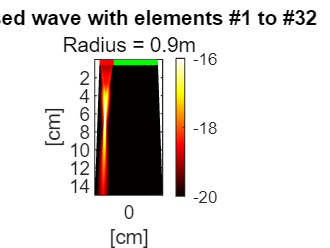

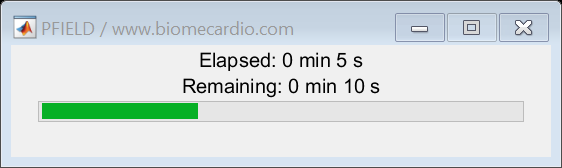

% In all working documents it is good practice to use "clear; close all;
% clc;" to clear the variables, figures, command window. 
% Aka will clear everything that could cause problems from previously saved
% varibles, functions, etc.
clear; close all; clc;

% Download the properties of a 3.6-MHz 128-element 
% curved linear array in a structure param by using GETPARAM.
param = getparam('C5-2v');
r = [1.00e-3:1.00e-3:4.00e-3, 5.00e-3:5.00e-3:45.00e-3, 50.00e-3:50.00e-3:400.00e-3,1:1:3];

for i=r
    param = setfield(param,'radius',i);
    R = param.radius; % 0.0496 m
    p = param.pitch; % 5.080e-04 m
    N = param.Nelements;
    L = 2*R*sin(asin(p/2/R)*(N-1)); % chord length
    h = sqrt(R^2-L^2/4);
    th = linspace(atan2(-L/2,h),atan2(L/2,h),N);
    xe = R*sin(th);
    ze = R*cos(th)-h;
    
    % Creating a convex "sub-array" with 32 elements.
    param_suba = param;
    param_suba.Nelements = 32;
    
    % Define a focus location at xf = 0 cm, zf = 7.5 cm, 
    % relative to the sub-array
    xf = 0; zf = 7.5e-2; % focus position (in m)
    
    % Calculate the transmit time delays (in s) for the sub-array.
    txdel_suba = txdelay(xf,zf,param_suba); % in s
    
    % Obtain the transmit time delays (in s) for the (complete) array
    % when firing with elements #1 to #32
    txdel_1to32 = NaN(1,128);
    txdel_1to32(1:32) = txdel_suba;
    
    % Simulate the pressure fields by using PFIELD.
    % First define an image polar-type grid by using IMPOLGRID.
    [x,z] = impolgrid([128 128],15e-2,param);
    y = zeros(size(x));
    
    % The function PFIELD yields the root-mean-square (RMS) pressure fields.
    P_1to32 = pfield(x,y,z,txdel_1to32,param);
    
    % Display the acoustic pressure field when firing elements #1 to #32.
    pcolor(x*1e2,z*1e2,20*log10(P_1to32/max(P_1to32(:))))
        shading interp
        colormap hot
        axis equal tight ij
        caxis([-20 0]) % dynamic range = [-20,0] dB
        c = colorbar;
        c.YTickLabel{end} = '0 dB';
        xlabel('[cm]'), ylabel('[cm]')
        title('Focused wave with elements #1 to #32')
        subtitle(['Radius = ' num2str(R) 'm'])
        
        hold on
        plot(xe*1e2,ze*1e2,'g','Linewidth',5)
        plot(xe(1:32)*1e2,ze(1:32)*1e2,'r','Linewidth',5)
        hold off
    
    saveas(gcf,['Radius ' num2str(R*1000) 'mm.jpg'])
end 

# Changing Frequency for a Curved linear Array

clear; clear all; clc;

param = getparam('C5-2v');

param = struct with fields:
    fc: 8000000


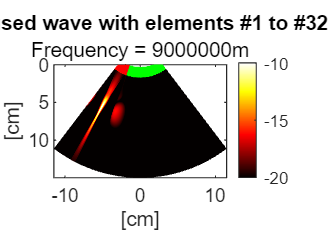


for fc = [0.07e6:0.05e6:0.97e6, 1e6:1e6:9e6]
    param = setfield(param,'fc',fc);
        R = param.radius; % 0.0496 m
        p = param.pitch; % 5.080e-04 m
        N = param.Nelements;
        L = 2*R*sin(asin(p/2/R)*(N-1)); % chord length
        h = sqrt(R^2-L^2/4);
        th = linspace(atan2(-L/2,h),atan2(L/2,h),N);
        xe = R*sin(th);
        ze = R*cos(th)-h;
    
    % Creating a convex "sub-array" with 32 elements.
    param_suba = param;
    param_suba.Nelements = 32;
    xf = 0; zf = 7.5e-2; % focus position (in m)
    
    % Calculate the transmit time delays (in s) for the sub-array.
    txdel_suba = txdelay(xf,zf,param_suba); % in s
    
    % Obtain the transmit time delays (in s) for the (complete) array
    % when firing with elements #1 to #32
    txdel_1to32 = NaN(1,128);
    txdel_1to32(1:32) = txdel_suba;   
    [x,z] = impolgrid([128 128],15e-2,param);
    y = zeros(size(x));
    
    P_1to32 = pfield(x,y,z,txdel_1to32,param);
    
    pcolor(x*1e2,z*1e2,20*log10(P_1to32/max(P_1to32(:))))
        shading interp
        colormap hot
        axis equal tight ij
        caxis([-20 0]) % dynamic range = [-20,0] dB
        c = colorbar;
        c.YTickLabel{end} = '0 dB';
        xlabel('[cm]'), ylabel('[cm]')
        title('Focused wave with elements #1 to #32')
        subtitle(['Frequency = ' num2str(fc) 'm'])
        
        hold on
        plot(xe*1e2,ze*1e2,'g','Linewidth',5)
        plot(xe(1:32)*1e2,ze(1:32)*1e2,'r','Linewidth',5)
        hold off
    
    saveas(gcf,['C5V2 Freq' num2str(fc/1000000) 'MHz.jpg'])
end 

## CODE BELOW DOES NOT FUNCTION PROPERLY

% gifs were created using an external code made by Atishna Samantaray 

% clc
% clear
% gif_fps = 24; 
% video_filename = 'Radius 0.03:0.01:0.04.gif';
% fh = figure;
% r = 0.03:0.001:0.04

r =     0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400


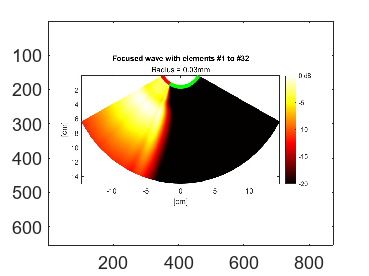

Error using matlab.internal.fopen
Unable to find file. Ensure file exists and path is
valid.

Error in imwrite (line 537)
fid = matlab.internal.fopen(filename, 'a');

% for i=r
%     F_data = imread([num2str(i) '.jpg']);
%     imagesc(F_data);
%     drawnow;
%     frame = getframe(fh);
%     im = frame2im(frame);
%     [imind,cm] = rgb2ind(im,256);
%     if i == 0.003
%         imwrite(imind,cm,video_filename,'gif', 'Loopcount',inf);
%     else
%         imwrite(imind,cm,video_filename,'gif','WriteMode','append','DelayTime',1/gif_fps);
%     end
% end

% %% 
% folder = pwd; % Or wherever you want.
% video = VideoWriter('changes.avi'); % Create the video object.
% open(video); % Open the file for writing
% N=35; % Where N is the separate number of PNG image files.
% for k = 1 : N 
%     I = imread(fullfile(folder, sprintf('%g.jpg', k))); % Read the next image from disk.
%     writeVideo(video,I); % Write the image to file.
% end
% close(video);